% this script showcases a collection of functions for reading and writing
% information to EPA-SWMM.


path_project2 = mfilename('fullpath');

% specify path for SWMM .INP file
ffile_model_parent = 'C:\Users\everett\Google Drive\02_phd\00_projects_major\02_swmm_calibration\src\functions\swmm\example\example.inp';

% specify destination folder for SWMM .INP file copy
path_new = 'C:\Users\everett\Google Drive\02_phd\00_projects_major\02_swmm_calibration\src\functions\swmm\example\calibration\';

% initialize model - this script creates a fresh copy (called the child) of the original .INP
% file (called the parent)
% the function also creates a .BAT file, to compute the child .INP file
ffile_model = swmm_initialize(ffile_model_parent,path_new);

existing child model found, deleting...
parent model found, creating copy of .inp file...



% get data associated with a class
data_sc = swmm_class(ffile_model,{'subcatchments'})

data_sc = 3×10 table
            Name    Rain_Gage    Outlet    Area    PercentImperv    Width    PercentSlope    CurbLen    SnowPack    line_num
            ____    _________    ______    ____    _____________    _____    ____________    _______    ________    ________

    sc_1    'S1'     'rg_1'       'J1'      4           50           400         0.5            0          ''          57   
    sc_2    'S2'     'rg_1'       'J2'      4           10           400         0.5            0          ''          58   
    sc_3    'S3'     'rg_1'       'J3'      4           90           400         0.5   


% change the attribute value for a specific subcatchment
swmm_elements(ffile_model,{'subcatchments'},{'PercentImperv'},{'S1'},20)

ans = 1×1 cell array
    {[50]}



% compute the model
swmm_execute(ffile_model)


% read the subcatchments data again, to confirm the new subcatchment value
data_sc = swmm_class(ffile_model,{'subcatchments'})

data_sc = 3×10 table
            Name    Rain_Gage    Outlet    Area    PercentImperv    Width    PercentSlope    CurbLen    SnowPack    line_num
            ____    _________    ______    ____    _____________    _____    ____________    _______    ________    ________

    sc_1    'S1'     'rg_1'       'J1'      4           20           400         0.5            0          ''          57   
    sc_2    'S2'     'rg_1'       'J2'      4           10           400         0.5            0          ''          58   
    sc_3    'S3'     'rg_1'       'J3'      4           90           400         0.5   

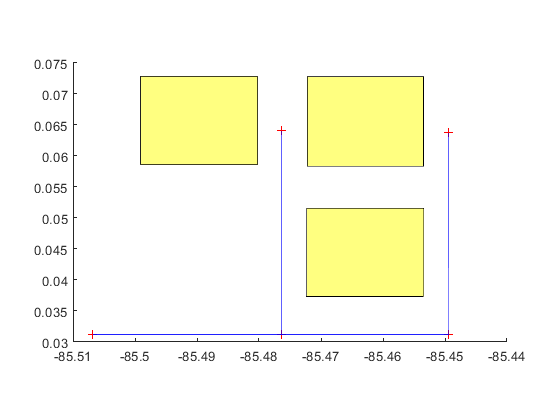


% create shapefiles for the various model classes
swmm_draw(ffile_model)

% plot the shapefiles
figure
swmm_shapes = {'subcatchments','junctions', 'outfalls', 'conduits'};
for i2 = 1:numel(swmm_shapes)
    s = shaperead([path_new,'\','shapefiles\',swmm_shapes{i2},'.shp']);
    mapshow(s);
end

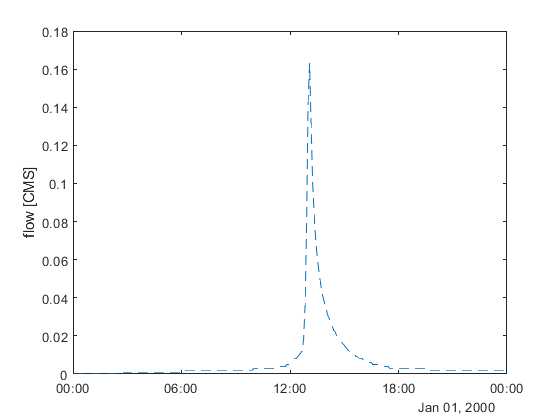


% read and plot the timetable data for a specific conduit
tt_out = swmm_timetable(ffile_model, 'Link','C4');
varname = 'flow';
plot(tt_out.Properties.RowTimes,tt_out(:,'flow').Variables,'--')
ylabel([varname,' [',char(tt_out(:,varname).Properties.VariableUnits),']'])


% read and plot the timetable data for three subcatchments
tt_scs = swmm_timetable(ffile_model, repmat({'subcatchment'},[1,3]),{'S1','S2','S3'});
figure
varname = 'runoff'

varname = 'runoff'

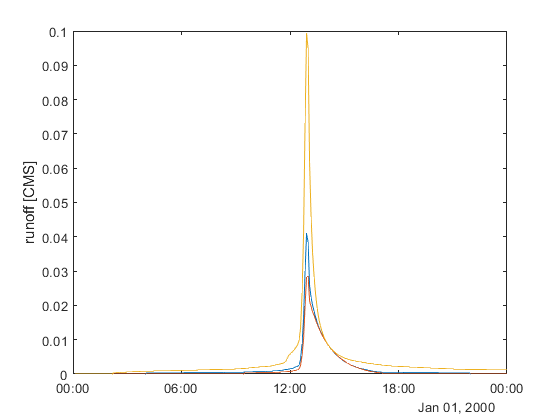

for i2 = 1:height(data_sc)
    plot(tt_scs{i2}.Properties.RowTimes,tt_scs{i2}(:,varname).Variables)
    hold on
end
ylabel([varname,' [',char(tt_scs{i2}(:,varname).Properties.VariableUnits),']'])